read_file = fopen('chr2_shapes_2nd.txt','rt');
% write_file = fopen('chr1_shape_matrices_2nd.txt', 'wt');
thisline = fgetl(read_file);
thisline = fgetl(read_file);
C = strsplit(thisline,"\t");
n1 = C(1,1);
n1 = str2double(n1{1});
MGW = C(1,3);
MGW = str2double(MGW{1});
prot = C(1,4);
prot = str2double(prot{1});
roll = C(1,5);
roll = str2double(roll{1});
heit = C(1,6);
heit = str2double(heit{1});

matrx = [MGW, prot, roll, heit];
n = [n1];

for k=1:21
    thisline = fgetl(read_file);
    C = strsplit(thisline,"\t");
    n1 = C(1,1);
    n1 = str2double(n1{1});

    MGW = C(1,3);
    MGW = str2double(MGW{1});
    prot = C(1,4);
    prot = str2double(prot{1});
    roll = C(1,5);
    roll = str2double(roll{1});
    heit = C(1,6);
    heit = str2double(heit{1});
    
    matrx = [matrx; MGW, prot, roll, heit];
    n = [n; n1];
end

matrx

matrx =     0.4185    0.3330    0.2151    0.3510
    0.3434    0.2723    0.1681    0.3618
    0.2895    0.2787    0.3538    0.2325
    0.3434    0.2723    0.3538    0.2325
    0.3829    0.3590    0.1599    0.3548
    0.3344    0.6516    0.2119    0.3038
    0.3413    0.8476    0.2129    0.1557
    0.4232    0.7441    0.1945    0.1233
    0.4765    0.6763    0.3231    0.0733
    0.4232    0.7441    0.3231    0.0733


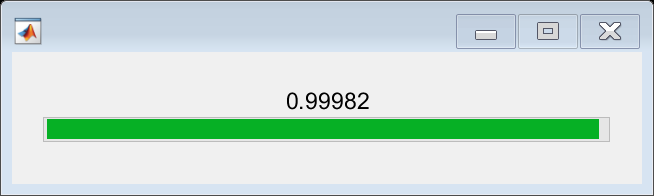


initial2 = repmat([0], 10124924, 88);

loading = waitbar(0,'Please wait...');
for i=1:123289
    r = i/123289;
    progress = round(r,5);
    waitbar(progress,loading,string(progress));
    
    matrx_row = matrx(:)';
    n_current = n(1, 1);
    
    initial2(n_current, :) = matrx_row;
     
%     fprintf(write_file,'%12d\t %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f\n',n_current, matrx_row);
    
    thisline = fgetl(read_file);
    if ~ischar(thisline); break; end  %end of file
    
    n(1, :) = [];
    matrx(1, :) = [];
    
    C = strsplit(thisline,"\t");
    n1 = C(1,1);
    n1 = str2double(n1{1});

    MGW = C(1,3);
    MGW = str2double(MGW{1});
    prot = C(1,4);
    prot = str2double(prot{1});
    roll = C(1,5);
    roll = str2double(roll{1});
    heit = C(1,6);
    heit = str2double(heit{1});
    
    matrx = [matrx; MGW, prot, roll, heit];
    n = [n; n1];
end


fclose(read_file);
% fclose(write_file);

initial2(11429, :)

ans =     0.3394    0.3187    0.3564    0.4698    0.6050    0.6295    0.5883    0.5103    0.5716    0.7687    0.6730    0.5357    0.4950    0.4262    0.4066    0.4046    0.4475    0.5134    0.3533    0.2194    0.3653    0.6516    0.8710    0.8601    0.7556    0.6885    0.6204    0.5791    0.6026    0.6595    0.6762    0.4106    0.2595    0.3022    0.4901    0.5101    0.4947    0.3993    0.2922    0.3565    0.5542    0.5623    0.3529    0.4689    0.1958    0.1794    0.1857    0.2023    0.3570    0.3890


save("chr2shapes2", "initial2", '-v7.3')

initial2(11429, :)

ans =     0.3394    0.3187    0.3564    0.4698    0.6050    0.6295    0.5883    0.5103    0.5716    0.7687    0.6730    0.5357    0.4950    0.4262    0.4066    0.4046    0.4475    0.5134    0.3533    0.2194    0.3653    0.6516    0.8710    0.8601    0.7556    0.6885    0.6204    0.5791    0.6026    0.6595    0.6762    0.4106    0.2595    0.3022    0.4901    0.5101    0.4947    0.3993    0.2922    0.3565    0.5542    0.5623    0.3529    0.4689    0.1958    0.1794    0.1857    0.2023    0.3570    0.3890


save("chr2shapes2", "initial2", '-v7.3')